load RADIOMREF
load GRAYREF
str = 'layer_grayref_1_img_';
nbimg=5;
m=zeros(4,1250000)

m =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


nb_col=1

nb_col = 1

for i=1:500
    for k=1:500
        for u=1:nbimg
        img=RADIOMREF{u};    
        classimg=GRAYREF{u};
        m(1,nb_col)=img(i,k,1);
        m(2,nb_col)=img(i,k,2);
        m(3,nb_col)=img(i,k,3);
        m(4,nb_col)=img(i,k,4);
        nb_col=nb_col+1;
        end
    end
end

nb_col

nb_col = 1250001

m_trans=transpose(m)

m_trans =     36    40    36    28
    32    32    28    28
    36    36    40    32
    28    28    28    28
    28    28    32    32
    40    40    36    32
    32    32    28    28
    45    40    45    36
    28    28    28    28
    28    32    32    32




n=1

n = 1

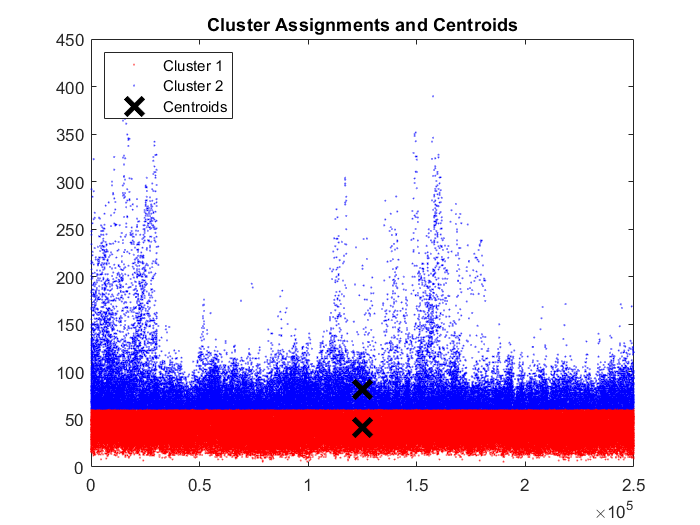

score=[];
% filename="C:\Users\Najmeddine\Desktop\Zaghouan\Tous les profiles temporelles\"
% f=1;
while n<1250001
    ex=m_trans(n:n+4,:);
%     out{f} = sprintf('%s%d%s',filename,f,".png");
%     imwrite (uint8 (ex),  out{f});
%     %save(out{n},'ex')
%     f=f+1;
    
    Y = pdist(ex,'euclidean');
    score=[score;max(Y)]; 
    n=n+5;
end

%scoreMatFile=matfile('SaveScore.mat');
% score=scoreMatFile.score

x=[1:1:250000];
vecSc=reshape(score,[250000,1]);
[idx,C]=kmeans(vecSc,2,'Distance','sqeuclidean','Replicates',100);
plot(x(idx==1),vecSc(idx==1),'r.','MarkerSize',1)
hold on
plot(x(idx==2),vecSc(idx==2),'b.','MarkerSize',1)
plot([125000;125000],C(:),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off



stableClusterMax=C(1,1)+sqrt(var(vecSc(idx==1)));
unStableClusterMin=C(2,1)+sqrt(var(vecSc(idx==1)));
idxStable=find(score<stableClusterMax);
idxUnStable=find(score>unStableClusterMin);


stablePixel=[]


stablePixel =

     []



nbStablePixel=1;
filename="C:\Users\Najmeddine\Desktop\Zaghouan\Stable Pixels Img\"

filename = "C:\Users\Najmeddine\Desktop\Zaghouan\Stable Pixels Img\"

% for h=1:size(idxStable)
%     stablePixel=m_trans((idxStable(h,1)-1)*5+1:(idxStable(h,1)-1)*5+1+4,:);
%     out{nbStablePixel} = sprintf('%s%d%s',filename,nbStablePixel,".png");
%     imwrite (uint8 (stablePixel),  out{nbStablePixel});
%    % save(out{nbStablePixel},'stablePixel')
%     nbStablePixel=nbStablePixel+1;
% end

%%% How to load a stable pixe !!!
% example = matfile('C:\Users\Najmeddine\Desktop\Zaghouan\Stable Pixels\4.mat');
% ex1=example.stablePixel


unStablePixel=[]


unStablePixel =

     []



nbUnStablePixel=1;
filename="C:\Users\Najmeddine\Desktop\Zaghouan\unStable Pixels Img\"

filename = "C:\Users\Najmeddine\Desktop\Zaghouan\unStable Pixels Img\"

% for u=1:size(idxUnStable)
%     unStablePixel=m_trans((idxUnStable(u,1)-1)*5+1:(idxUnStable(u,1)-1)*5+1+4,:);
%     out{nbUnStablePixel} = sprintf('%s%d%s',filename,nbUnStablePixel,".png");
%     imwrite (uint8 (unStablePixel),  out{nbUnStablePixel});
%    % save(out{nbUnStablePixel},'unStablePixel')
%     nbUnStablePixel=nbUnStablePixel+1;
% end

%%% How to load an Unstable pixe !!!
% example = matfile('C:\Users\Najmeddine\Desktop\Zaghouan\unStable Pixels\4.mat');
% ex1=example.unStablePixel